%% BLOCK 1: INITIAL SETUP AND DATA LOADING
clc; clear; close all;

rng(42, 'twister');
fprintf('========================================\n');

fprintf('K-FOLD CROSS-VALIDATION FOR VOWEL A\n');

K-FOLD CROSS-VALIDATION FOR VOWEL A


fprintf('========================================\n\n');

% Configuration
FREQ_MIN = 0.1;
FREQ_MAX = 450;
SAMPLE_RATE = 12500;
K_FOLDS = 5;  % Number of folds

% Load training data only
fprintf('=== Loading Training Data ===\n');

=== Loading Training Data ===


tic;
trainData = load('trainv2.mat');
FinalTableTrain = trainData.FinalTable;
clear trainData;
fprintf(' Loaded in %.1f sec\n', toc);

 Loaded in 469.4 sec


fprintf('  Total rows: %d\n\n', height(FinalTableTrain));

  Total rows: 701



%% BLOCK 2: PROCESS LABELS
fprintf('=== Processing Labels ===\n');

=== Processing Labels ===



% Normalize labels
v = upper(strtrim(FinalTableTrain.Vowels));
v(v == "" | v == "N" | v == "NONE") = "";
FinalTableTrain.Vowels = v;

% Add multi-hot encoding
FinalTableTrain = addVowelsMultiHot(FinalTableTrain);

Multi-hot encoding added:
  isA: 215 samples
  isE: 274 samples
  isI: 86 samples
  isO: 283 samples
  isU: 86 samples



% Extract Vowel A labels
Ytrain_A = double(FinalTableTrain.isA);

fprintf('Label distribution:\n');

Label distribution:


fprintf('  Present (1): %d (%.1f%%)\n', sum(Ytrain_A==1), 100*sum(Ytrain_A==1)/length(Ytrain_A));

  Present (1): 215 (30.7%)


fprintf('  Absent (0):  %d (%.1f%%)\n\n', sum(Ytrain_A==0), 100*sum(Ytrain_A==0)/length(Ytrain_A));

  Absent (0):  486 (69.3%)



%% BLOCK 3: FILTER WORDS TO EXACTLY 5 REPETITIONS PER WORD
fprintf('=== Filtering to 5 Repetitions per Word ===\n');

=== Filtering to 5 Repetitions per Word ===



% Check if 'Word' column exists
if ~ismember('word', FinalTableTrain.Properties.VariableNames)
    error('Column "Word" not found in table. Available columns: %s', ...
          strjoin(FinalTableTrain.Properties.VariableNames, ', '));
end

% Get unique words and their counts
uniqueWords = unique(FinalTableTrain.word);
fprintf('Total unique words: %d\n', length(uniqueWords));

Total unique words: 131



% Identify rows to keep (5 per word)
rowsToKeep = [];

for i = 1:length(uniqueWords)
    word = uniqueWords{i};
    wordIdx = find(strcmp(FinalTableTrain.word, word));
    
    numReps = length(wordIdx);
    
    if numReps >= 5
        % Keep first 5 occurrences
        rowsToKeep = [rowsToKeep; wordIdx(1:5)];
    end
end

% Sort to maintain order
rowsToKeep = sort(rowsToKeep);

% Filter the table
FinalTableTrain = FinalTableTrain(rowsToKeep, :);
Ytrain_A = Ytrain_A(rowsToKeep);

fprintf('\n Filtered dataset:\n');


 Filtered dataset:


fprintf('  Rows after filtering: %d\n', height(FinalTableTrain));

  Rows after filtering: 645


fprintf('  Expected rows (words × 5): %d\n\n', length(uniqueWords) * 5);

  Expected rows (words × 5): 655



%% BLOCK 4: EXTRACT FEATURES FOR ALL DATA
fprintf('=== Extracting Features ===\n');

=== Extracting Features ===


fprintf('This will take several minutes...\n\n');

This will take several minutes...




N = height(FinalTableTrain);
X_all = cell(N, 1);

tic;
for i = 1:N
    X_all{i} = extractLSTMFeatures(FinalTableTrain, i, FREQ_MIN, FREQ_MAX, SAMPLE_RATE);
    
    if mod(i, 100) == 0 || i == N
        elapsed = toc;
        pct = 100 * i / N;
        eta = elapsed * (N - i) / i;
        fprintf('  [%6d/%6d] %.1f%% | Elapsed: %.1fm | ETA: %.1fm\n', ...
            i, N, pct, elapsed/60, eta/60);
    end
end

  [   100/   645] 15.5% | Elapsed: 0.0m | ETA: 0.2m
  [   200/   645] 31.0% | Elapsed: 0.0m | ETA: 0.1m
  [   300/   645] 46.5% | Elapsed: 0.1m | ETA: 0.1m
  [   400/   645] 62.0% | Elapsed: 0.1m | ETA: 0.0m
  [   500/   645] 77.5% | Elapsed: 0.1m | ETA: 0.0m
  [   600/   645] 93.0% | Elapsed: 0.1m | ETA: 0.0m
  [   645/   645] 100.0% | Elapsed: 0.1m | ETA: 0.0m



totalTime = toc;
fprintf('\n✓ Feature extraction complete (%.1f min)\n', totalTime/60);


✓ Feature extraction complete (0.1 min)



[numFeatures, seqLength] = size(X_all{1});
fprintf('  Feature shape: %d features × %d timesteps\n\n', numFeatures, seqLength);

  Feature shape: 900 features × 39 timesteps



%% BLOCK 5: CREATE WORD-BASED K-FOLD SPLITS (NO DATA LEAKAGE)
fprintf('=== Creating %d-Fold Word-Based Splits ===\n', K_FOLDS);

=== Creating 5-Fold Word-Based Splits ===



uniqueWords = unique(FinalTableTrain.word, 'stable');
numWords = length(uniqueWords);

fprintf('Total words: %d\n', numWords);

Total words: 129


fprintf('Samples per word: 5\n');

Samples per word: 5


fprintf('Words per fold: ~%d\n\n', floor(numWords / K_FOLDS));

Words per fold: ~25




% Shuffle words randomly
shuffledWords = uniqueWords(randperm(numWords));

% Assign words to folds
wordsPerFold = floor(numWords / K_FOLDS);
foldAssignments = cell(K_FOLDS, 1);

for k = 1:K_FOLDS
    if k < K_FOLDS
        foldAssignments{k} = shuffledWords((k-1)*wordsPerFold + 1 : k*wordsPerFold);
    else
        % Last fold gets remaining words
        foldAssignments{k} = shuffledWords((k-1)*wordsPerFold + 1 : end);
    end
    fprintf('Fold %d: %d words assigned\n', k, length(foldAssignments{k}));
end

Fold 1: 25 words assigned
Fold 2: 25 words assigned
Fold 3: 25 words assigned
Fold 4: 25 words assigned
Fold 5: 29 words assigned



% Create index mapping for each fold
foldIndices = cell(K_FOLDS, 1);

for k = 1:K_FOLDS
    foldWords = foldAssignments{k};
    foldIdx = [];
    
    for w = 1:length(foldWords)
        wordRows = find(strcmp(FinalTableTrain.word, foldWords{w}));
        foldIdx = [foldIdx; wordRows];
    end
    
    foldIndices{k} = sort(foldIdx);
    fprintf('Fold %d: %d samples (rows)\n', k, length(foldIndices{k}));
end

Fold 1: 125 samples (rows)
Fold 2: 125 samples (rows)
Fold 3: 125 samples (rows)
Fold 4: 125 samples (rows)
Fold 5: 145 samples (rows)



fprintf('\n✓ K-Fold splits created (word-based, no leakage)\n\n');


✓ K-Fold splits created (word-based, no leakage)



%% BLOCK 6: INITIALIZE STORAGE FOR RESULTS
fprintf('=== Initializing Result Storage ===\n');

=== Initializing Result Storage ===



% Metrics storage
metrics = struct();
metrics.train_acc = zeros(K_FOLDS, 1);
metrics.train_prec = zeros(K_FOLDS, 1);
metrics.train_rec = zeros(K_FOLDS, 1);
metrics.train_f1 = zeros(K_FOLDS, 1);
metrics.train_spec = zeros(K_FOLDS, 1);
metrics.train_sens = zeros(K_FOLDS, 1);

metrics.val_acc = zeros(K_FOLDS, 1);
metrics.val_prec = zeros(K_FOLDS, 1);
metrics.val_rec = zeros(K_FOLDS, 1);
metrics.val_f1 = zeros(K_FOLDS, 1);
metrics.val_spec = zeros(K_FOLDS, 1);
metrics.val_sens = zeros(K_FOLDS, 1);

% ROC storage (for aggregation)
roc_data = struct();
roc_data.train_scores = cell(K_FOLDS, 1);
roc_data.train_labels = cell(K_FOLDS, 1);
roc_data.val_scores = cell(K_FOLDS, 1);
roc_data.val_labels = cell(K_FOLDS, 1);

% Confusion matrix storage
val_confusion_total = zeros(2, 2);  % Aggregate across folds

fprintf(' Storage initialized for %d folds\n\n', K_FOLDS);

 Storage initialized for 5 folds



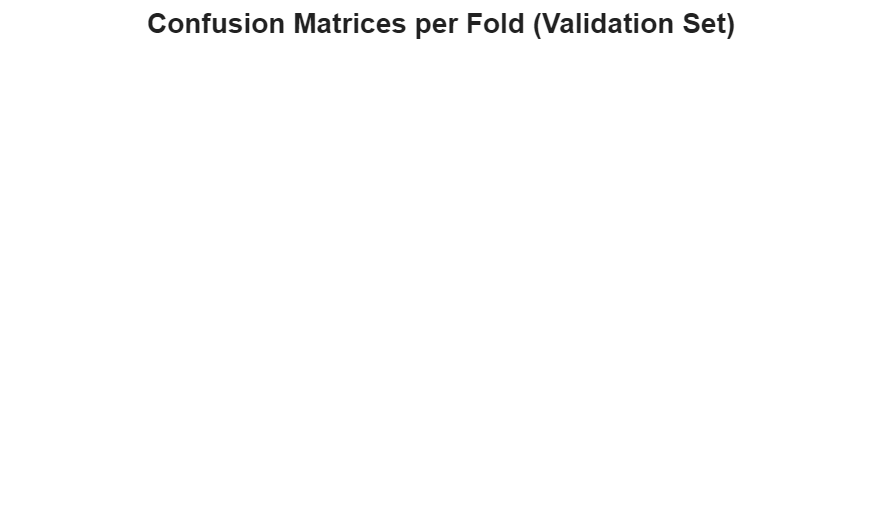

%% BLOCK 6.5: SETUP VISUALIZATION
% Create a single figure to hold all 5 confusion matrices
hFigCM = figure('Name', 'Confusion Matrices by Fold', 'Position', [100, 100, 1200, 700], 'Color', 'w');
tlo = tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tlo, 'Confusion Matrices per Fold (Validation Set)', 'FontSize', 14, 'FontWeight', 'bold');

%% BLOCK 7: K-FOLD TRAINING LOOP
fprintf('========================================\n');

fprintf('STARTING %d-FOLD CROSS-VALIDATION\n', K_FOLDS);

STARTING 5-FOLD CROSS-VALIDATION


fprintf('========================================\n\n');

╔══════════════════════════════════════╗


║         FOLD 1 / 5                   ║


╚══════════════════════════════════════╝



--- Splitting Data ---


  Training samples: 520


  Validation samples: 125


  Train - Absent: 360, Present: 160


  Val   - Absent: 90, Present: 35



--- Augmenting Training Data ---


  Generating 200 augmented samples...


  ✓ Balanced - Absent: 360, Present: 360



--- Normalizing Features ---


 Normalized using training statistics



--- Building LSTM Model ---


   Model architecture ready



--- Training (Fold 1) ---


   Training complete (3.7 min)



--- Evaluating Training Set ---


  Accuracy:    93.75%


  Precision:   97.58%


  Recall:      89.72%


  Sensitivity: 89.72%


  Specificity: 97.78%


  F1-Score:    93.49%



--- Evaluating Validation Set ---


  Accuracy:    77.60%


  Precision:   60.00%


  Recall:      60.00%


  Sensitivity: 60.00%


  Specificity: 84.44%


  F1-Score:    60.00%



 Fold 1 complete


╔══════════════════════════════════════╗


║         FOLD 2 / 5                   ║


╚══════════════════════════════════════╝



--- Splitting Data ---


  Training samples: 520


  Validation samples: 125


  Train - Absent: 370, Present: 150


  Val   - Absent: 80, Present: 45



--- Augmenting Training Data ---


  Generating 220 augmented samples...


  ✓ Balanced - Absent: 370, Present: 370



--- Normalizing Features ---


 Normalized using training statistics



--- Building LSTM Model ---


   Model architecture ready



--- Training (Fold 2) ---


   Training complete (3.4 min)



--- Evaluating Training Set ---


  Accuracy:    94.59%


  Precision:   94.12%


  Recall:      95.14%


  Sensitivity: 95.14%


  Specificity: 94.05%


  F1-Score:    94.62%



--- Evaluating Validation Set ---


  Accuracy:    69.60%


  Precision:   64.00%


  Recall:      35.56%


  Sensitivity: 35.56%


  Specificity: 88.75%


  F1-Score:    45.71%



 Fold 2 complete


╔══════════════════════════════════════╗


║         FOLD 3 / 5                   ║


╚══════════════════════════════════════╝



--- Splitting Data ---


  Training samples: 520


  Validation samples: 125


  Train - Absent: 375, Present: 145


  Val   - Absent: 75, Present: 50



--- Augmenting Training Data ---


  Generating 230 augmented samples...


  ✓ Balanced - Absent: 375, Present: 375



--- Normalizing Features ---


 Normalized using training statistics



--- Building LSTM Model ---


   Model architecture ready



--- Training (Fold 3) ---


   Training complete (3.4 min)



--- Evaluating Training Set ---


  Accuracy:    93.60%


  Precision:   98.23%


  Recall:      88.80%


  Sensitivity: 88.80%


  Specificity: 98.40%


  F1-Score:    93.28%



--- Evaluating Validation Set ---


  Accuracy:    76.00%


  Precision:   88.46%


  Recall:      46.00%


  Sensitivity: 46.00%


  Specificity: 96.00%


  F1-Score:    60.53%



 Fold 3 complete


╔══════════════════════════════════════╗


║         FOLD 4 / 5                   ║


╚══════════════════════════════════════╝



--- Splitting Data ---


  Training samples: 520


  Validation samples: 125


  Train - Absent: 355, Present: 165


  Val   - Absent: 95, Present: 30



--- Augmenting Training Data ---


  Generating 190 augmented samples...


  ✓ Balanced - Absent: 355, Present: 355



--- Normalizing Features ---


 Normalized using training statistics



--- Building LSTM Model ---


   Model architecture ready



--- Training (Fold 4) ---


   Training complete (1.1 min)



--- Evaluating Training Set ---


  Accuracy:    81.83%


  Precision:   90.94%


  Recall:      70.70%


  Sensitivity: 70.70%


  Specificity: 92.96%


  F1-Score:    79.56%



--- Evaluating Validation Set ---


  Accuracy:    75.20%


  Precision:   47.83%


  Recall:      36.67%


  Sensitivity: 36.67%


  Specificity: 87.37%


  F1-Score:    41.51%



 Fold 4 complete


╔══════════════════════════════════════╗


║         FOLD 5 / 5                   ║


╚══════════════════════════════════════╝



--- Splitting Data ---


  Training samples: 500


  Validation samples: 145


  Train - Absent: 340, Present: 160


  Val   - Absent: 110, Present: 35



--- Augmenting Training Data ---


  Generating 180 augmented samples...


  ✓ Balanced - Absent: 340, Present: 340



--- Normalizing Features ---


 Normalized using training statistics



--- Building LSTM Model ---


   Model architecture ready



--- Training (Fold 5) ---


   Training complete (1.7 min)



--- Evaluating Training Set ---


  Accuracy:    87.94%


  Precision:   88.86%


  Recall:      86.76%


  Sensitivity: 86.76%


  Specificity: 89.12%


  F1-Score:    87.80%



--- Evaluating Validation Set ---


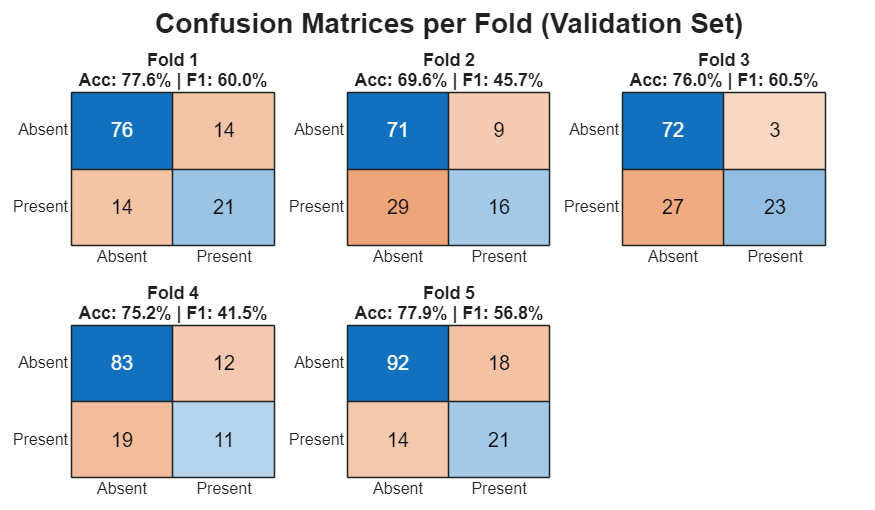

  Accuracy:    77.93%


  Precision:   53.85%


  Recall:      60.00%


  Sensitivity: 60.00%


  Specificity: 83.64%


  F1-Score:    56.76%



 Fold 5 complete



for fold = 1:K_FOLDS
    fprintf('\n');
    fprintf('╔══════════════════════════════════════╗\n');
    fprintf('║         FOLD %d / %d                   ║\n', fold, K_FOLDS);
    fprintf('╚══════════════════════════════════════╝\n\n');
    
    %% SPLIT DATA
    fprintf('--- Splitting Data ---\n');
    
    % Validation indices for this fold
    valIdx = foldIndices{fold};
    
    % Training indices (all other folds)
    trainIdx = [];
    for k = 1:K_FOLDS
        if k ~= fold
            trainIdx = [trainIdx; foldIndices{k}];
        end
    end
    
    % Split features and labels
    Xtrain = X_all(trainIdx);
    Ytrain = Ytrain_A(trainIdx);
    
    Xval = X_all(valIdx);
    Yval = Ytrain_A(valIdx);
    
    fprintf('  Training samples: %d\n', length(Ytrain));
    fprintf('  Validation samples: %d\n', length(Yval));
    
    % Check class distribution
    fprintf('  Train - Absent: %d, Present: %d\n', sum(Ytrain==0), sum(Ytrain==1));
    fprintf('  Val   - Absent: %d, Present: %d\n', sum(Yval==0), sum(Yval==1));
    
    %% DATA AUGMENTATION
    fprintf('\n--- Augmenting Training Data ---\n');
    
    idx0 = find(Ytrain == 0);
    idx1 = find(Ytrain == 1);
    
    if length(idx0) < length(idx1)
        minority_idx = idx0;
        minority_label = 0;
        targetN = length(idx1);
    else
        minority_idx = idx1;
        minority_label = 1;
        targetN = length(idx0);
    end
    
    numToGenerate = targetN - length(minority_idx);
    fprintf('  Generating %d augmented samples...\n', numToGenerate);
    
    noise_std = 0.05;
    augmented_features = cell(numToGenerate, 1);
    augmented_labels = zeros(numToGenerate, 1);
    
    for i = 1:numToGenerate
        source_idx = minority_idx(randi(length(minority_idx)));
        original = Xtrain{source_idx};
        noise = noise_std * randn(size(original), 'single');
        augmented_features{i} = original + noise;
        augmented_labels(i) = minority_label;
    end
    
    % Combine original + augmented
    XtrainAug = [Xtrain; augmented_features];
    YtrainAug_numeric = [Ytrain; augmented_labels];
    
    fprintf('  ✓ Balanced - Absent: %d, Present: %d\n', ...
        sum(YtrainAug_numeric==0), sum(YtrainAug_numeric==1));
    
    %% NORMALIZATION (Standard Scaler using TRAINING data only)
    fprintf('\n--- Normalizing Features ---\n');
    
    allTrainData = horzcat(XtrainAug{:});
    mu = mean(allTrainData, 2);
    sigma = std(allTrainData, 0, 2) + eps;
    
    % Apply to training
    for i = 1:length(XtrainAug)
        XtrainAug{i} = (XtrainAug{i} - mu) ./ sigma;
    end
    
    % Apply SAME normalization to validation
    for i = 1:length(Xval)
        Xval{i} = (Xval{i} - mu) ./ sigma;
    end
    
    fprintf(' Normalized using training statistics\n');
    
    % Convert to categorical
    YtrainAug_cat = categorical(YtrainAug_numeric, [0, 1], {'Absent', 'Present'});
    Yval_cat = categorical(Yval, [0, 1], {'Absent', 'Present'});
    
    %% BUILD MODEL
    fprintf('\n--- Building LSTM Model ---\n');
    
    layers = [
        sequenceInputLayer(numFeatures, 'Name', 'input')
        
        bilstmLayer(64, 'OutputMode', 'last', 'Name', 'bilstm1')
        batchNormalizationLayer('Name', 'bn1')
        dropoutLayer(0.5, 'Name', 'dropout1')
        
        fullyConnectedLayer(2, 'Name', 'fc_out')
        softmaxLayer('Name', 'softmax')
        classificationLayer('Name', 'output')
    ];
    
    options = trainingOptions('adam', ...
        'InitialLearnRate', 1e-4, ...
        'MaxEpochs', 30, ...
        'MiniBatchSize', 8, ...
        'Shuffle', 'every-epoch', ...
        'ValidationData', {Xval, Yval_cat}, ...
        'ValidationFrequency', 20, ...
        'ValidationPatience', 15, ...
        'ExecutionEnvironment', 'auto', ...
        'Plots', 'none', ...
        'Verbose', false, ...
        'GradientThreshold', 1, ...
        'SequenceLength', 'longest', ...
        'SequencePaddingDirection', 'right');
    
    fprintf('   Model architecture ready\n');
    
    %% TRAIN
    fprintf('\n--- Training (Fold %d) ---\n', fold);
    tic;
    net = trainNetwork(XtrainAug, YtrainAug_cat, layers, options);
    trainTime = toc;
    fprintf('   Training complete (%.1f min)\n', trainTime/60);
    
    %% EVALUATE TRAINING SET
    fprintf('\n--- Evaluating Training Set ---\n');
    
    [YPred_train, scores_train] = classify(net, XtrainAug);
    
    Ytrue_train = double(YtrainAug_cat == "Present");
    YPred_train_num = double(YPred_train == "Present");
    
    TP_tr = sum((YPred_train_num == 1) & (Ytrue_train == 1));
    FP_tr = sum((YPred_train_num == 1) & (Ytrue_train == 0));
    FN_tr = sum((YPred_train_num == 0) & (Ytrue_train == 1));
    TN_tr = sum((YPred_train_num == 0) & (Ytrue_train == 0));
    
    metrics.train_acc(fold) = (TP_tr + TN_tr) / length(Ytrue_train);
    metrics.train_prec(fold) = TP_tr / (TP_tr + FP_tr + eps);
    metrics.train_rec(fold) = TP_tr / (TP_tr + FN_tr + eps);
    metrics.train_sens(fold) = metrics.train_rec(fold);  % Sensitivity = Recall
    metrics.train_spec(fold) = TN_tr / (TN_tr + FP_tr + eps);
    metrics.train_f1(fold) = 2 * metrics.train_prec(fold) * metrics.train_rec(fold) / ...
                             (metrics.train_prec(fold) + metrics.train_rec(fold) + eps);
    
    fprintf('  Accuracy:    %.2f%%\n', metrics.train_acc(fold)*100);
    fprintf('  Precision:   %.2f%%\n', metrics.train_prec(fold)*100);
    fprintf('  Recall:      %.2f%%\n', metrics.train_rec(fold)*100);
    fprintf('  Sensitivity: %.2f%%\n', metrics.train_sens(fold)*100);
    fprintf('  Specificity: %.2f%%\n', metrics.train_spec(fold)*100);
    fprintf('  F1-Score:    %.2f%%\n', metrics.train_f1(fold)*100);
    
    % Store for ROC
    roc_data.train_scores{fold} = scores_train(:, 2);  % "Present" class probability
    roc_data.train_labels{fold} = YtrainAug_cat;
    
    %% EVALUATE VALIDATION SET
    fprintf('\n--- Evaluating Validation Set ---\n');
    
    [YPred_val, scores_val] = classify(net, Xval);
    
    Ytrue_val = double(Yval_cat == "Present");
    YPred_val_num = double(YPred_val == "Present");
    
    TP_val = sum((YPred_val_num == 1) & (Ytrue_val == 1));
    FP_val = sum((YPred_val_num == 1) & (Ytrue_val == 0));
    FN_val = sum((YPred_val_num == 0) & (Ytrue_val == 1));
    TN_val = sum((YPred_val_num == 0) & (Ytrue_val == 0));
    
    metrics.val_acc(fold) = (TP_val + TN_val) / length(Ytrue_val);
    metrics.val_prec(fold) = TP_val / (TP_val + FP_val + eps);
    metrics.val_rec(fold) = TP_val / (TP_val + FN_val + eps);
    metrics.val_sens(fold) = metrics.val_rec(fold);
    metrics.val_spec(fold) = TN_val / (TN_val + FP_val + eps);
    metrics.val_f1(fold) = 2 * metrics.val_prec(fold) * metrics.val_rec(fold) / ...
                           (metrics.val_prec(fold) + metrics.val_rec(fold) + eps);
    
    nexttile(tlo); % Select the next slot in the window
    
    % Create the chart for this specific fold
    cm_fold = confusionchart(Yval_cat, YPred_val);
    
    % Add detailed title with metrics
    title(sprintf('Fold %d\nAcc: %.1f%% | F1: %.1f%%', ...
        fold, metrics.val_acc(fold)*100, metrics.val_f1(fold)*100));
        
    % Sort classes to keep "Absent" first
    sortClasses(cm_fold, {'Absent', 'Present'});
    
    % Remove axis labels to save space
    cm_fold.XLabel = '';
    cm_fold.YLabel = '';
    
    fprintf('  Accuracy:    %.2f%%\n', metrics.val_acc(fold)*100);
    fprintf('  Precision:   %.2f%%\n', metrics.val_prec(fold)*100);
    fprintf('  Recall:      %.2f%%\n', metrics.val_rec(fold)*100);
    fprintf('  Sensitivity: %.2f%%\n', metrics.val_sens(fold)*100);
    fprintf('  Specificity: %.2f%%\n', metrics.val_spec(fold)*100);
    fprintf('  F1-Score:    %.2f%%\n', metrics.val_f1(fold)*100);
    
    % Accumulate confusion matrix
    val_confusion_total(1,1) = val_confusion_total(1,1) + TN_val;  % TN
    val_confusion_total(1,2) = val_confusion_total(1,2) + FP_val;  % FP
    val_confusion_total(2,1) = val_confusion_total(2,1) + FN_val;  % FN
    val_confusion_total(2,2) = val_confusion_total(2,2) + TP_val;  % TP
    
    % Store for ROC
    roc_data.val_scores{fold} = scores_val(:, 2);
    roc_data.val_labels{fold} = Yval_cat;
    
    fprintf('\n Fold %d complete\n', fold);
end


fprintf('\n');
fprintf('╔══════════════════════════════════════╗\n');

╔══════════════════════════════════════╗


fprintf('║   ALL %d FOLDS COMPLETED             ║\n', K_FOLDS);

║   ALL 5 FOLDS COMPLETED             ║


fprintf('╚══════════════════════════════════════╝\n\n');

╚══════════════════════════════════════╝



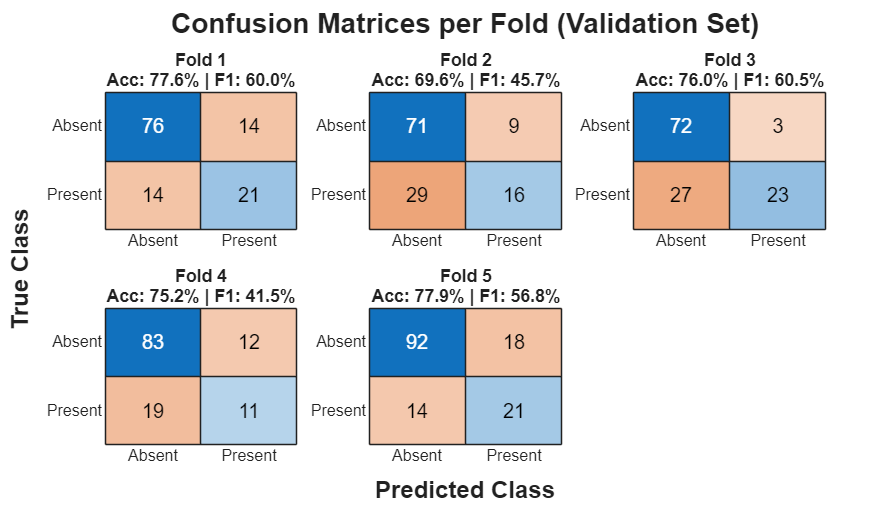

% Add shared labels to the layout
xlabel(tlo, 'Predicted Class', 'FontSize', 12, 'FontWeight', 'bold');
ylabel(tlo, 'True Class', 'FontSize', 12, 'FontWeight', 'bold');

%% BLOCK 8: DISPLAY FOLD-BY-FOLD RESULTS
fprintf('========================================\n');

fprintf('FOLD-BY-FOLD RESULTS\n');

FOLD-BY-FOLD RESULTS


fprintf('========================================\n\n');


fprintf('╔════════════════════════════════════════════════════════════════════════════════════════════════╗\n');

╔════════════════════════════════════════════════════════════════════════════════════════════════╗


fprintf('║  Fold  │     TRAINING METRICS      │      VALIDATION METRICS       │\n');

║  Fold  │     TRAINING METRICS      │      VALIDATION METRICS       │


fprintf('╠════════════════════════════════════════════════════════════════════════════════════════════════╣\n');

╠════════════════════════════════════════════════════════════════════════════════════════════════╣


fprintf('║        │  Acc   Prec   Rec    F1   │   Acc   Prec   Rec    F1      │\n');

║        │  Acc   Prec   Rec    F1   │   Acc   Prec   Rec    F1      │


fprintf('╠════════════════════════════════════════════════════════════════════════════════════════════════╣\n');

╠════════════════════════════════════════════════════════════════════════════════════════════════╣



for fold = 1:K_FOLDS
    fprintf('║   %d    │ %.2f  %.2f  %.2f  %.2f │  %.2f  %.2f  %.2f  %.2f     │\n', ...
        fold, ...
        metrics.train_acc(fold)*100, metrics.train_prec(fold)*100, ...
        metrics.train_rec(fold)*100, metrics.train_f1(fold)*100, ...
        metrics.val_acc(fold)*100, metrics.val_prec(fold)*100, ...
        metrics.val_rec(fold)*100, metrics.val_f1(fold)*100);
end

║   1    │ 93.75  97.58  89.72  93.49 │  77.60  60.00  60.00  60.00     │
║   2    │ 94.59  94.12  95.14  94.62 │  69.60  64.00  35.56  45.71     │
║   3    │ 93.60  98.23  88.80  93.28 │  76.00  88.46  46.00  60.53     │
║   4    │ 81.83  90.94  70.70  79.56 │  75.20  47.83  36.67  41.51     │
║   5    │ 87.94  88.86  86.76  87.80 │  77.93  53.85  60.00  56.76     │



fprintf('╚════════════════════════════════════════════════════════════════════════════════════════════════╝\n\n');

╚════════════════════════════════════════════════════════════════════════════════════════════════╝



%% BLOCK 9: CALCULATE AND DISPLAY MEAN ± STD
fprintf('========================================\n');

fprintf('AGGREGATED RESULTS (Mean ± Std)\n');

AGGREGATED RESULTS (Mean ± Std)


fprintf('========================================\n\n');


fprintf('TRAINING SET:\n');

TRAINING SET:


fprintf('  Accuracy:    %.2f%% ± %.2f%%\n', mean(metrics.train_acc)*100, std(metrics.train_acc)*100);

  Accuracy:    90.34% ± 5.44%


fprintf('  Precision:   %.2f%% ± %.2f%%\n', mean(metrics.train_prec)*100, std(metrics.train_prec)*100);

  Precision:   93.95% ± 4.08%


fprintf('  Recall:      %.2f%% ± %.2f%%\n', mean(metrics.train_rec)*100, std(metrics.train_rec)*100);

  Recall:      86.23% ± 9.21%


fprintf('  Sensitivity: %.2f%% ± %.2f%%\n', mean(metrics.train_sens)*100, std(metrics.train_sens)*100);

  Sensitivity: 86.23% ± 9.21%


fprintf('  Specificity: %.2f%% ± %.2f%%\n', mean(metrics.train_spec)*100, std(metrics.train_spec)*100);

  Specificity: 94.46% ± 3.79%


fprintf('  F1-Score:    %.2f%% ± %.2f%%\n\n', mean(metrics.train_f1)*100, std(metrics.train_f1)*100);

  F1-Score:    89.75% ± 6.28%




fprintf('VALIDATION SET:\n');

VALIDATION SET:


fprintf('  Accuracy:    %.2f%% ± %.2f%%\n', mean(metrics.val_acc)*100, std(metrics.val_acc)*100);

  Accuracy:    75.27% ± 3.36%


fprintf('  Precision:   %.2f%% ± %.2f%%\n', mean(metrics.val_prec)*100, std(metrics.val_prec)*100);

  Precision:   62.83% ± 15.59%


fprintf('  Recall:      %.2f%% ± %.2f%%\n', mean(metrics.val_rec)*100, std(metrics.val_rec)*100);

  Recall:      47.64% ± 11.99%


fprintf('  Sensitivity: %.2f%% ± %.2f%%\n', mean(metrics.val_sens)*100, std(metrics.val_sens)*100);

  Sensitivity: 47.64% ± 11.99%


fprintf('  Specificity: %.2f%% ± %.2f%%\n', mean(metrics.val_spec)*100, std(metrics.val_spec)*100);

  Specificity: 88.04% ± 4.92%


fprintf('  F1-Score:    %.2f%% ± %.2f%%\n\n', mean(metrics.val_f1)*100, std(metrics.val_f1)*100);

  F1-Score:    52.90% ± 8.73%




% Model stability assessment
fprintf('MODEL STABILITY ASSESSMENT:\n');

MODEL STABILITY ASSESSMENT:


val_f1_std = std(metrics.val_f1)*100;
if val_f1_std < 3.0
    fprintf('  ✓ EXCELLENT stability (F1 std: %.2f%%)\n', val_f1_std);
elseif val_f1_std < 5.0
    fprintf('  ✓ GOOD stability (F1 std: %.2f%%)\n', val_f1_std);
elseif val_f1_std < 8.0
    fprintf('  ⚠ MODERATE stability (F1 std: %.2f%%)\n', val_f1_std);
else
    fprintf('  ✗ POOR stability (F1 std: %.2f%%) - Consider more data or regularization\n', val_f1_std);
end

  ✗ POOR stability (F1 std: 8.73%) - Consider more data or regularization


fprintf('\n');

%% BLOCK 10: AGGREGATED VALIDATION CONFUSION MATRIX
fprintf('========================================\n');

fprintf('AGGREGATED VALIDATION CONFUSION MATRIX\n');

AGGREGATED VALIDATION CONFUSION MATRIX


fprintf('========================================\n\n');


TN_total = val_confusion_total(1,1);
FP_total = val_confusion_total(1,2);
FN_total = val_confusion_total(2,1);
TP_total = val_confusion_total(2,2);

% Calculate overall metrics from aggregated confusion matrix
acc_overall = (TP_total + TN_total) / sum(val_confusion_total(:));
prec_overall = TP_total / (TP_total + FP_total + eps);
rec_overall = TP_total / (TP_total + FN_total + eps);
sens_overall = rec_overall;
spec_overall = TN_total / (TN_total + FP_total + eps);
f1_overall = 2 * prec_overall * rec_overall / (prec_overall + rec_overall + eps);

fprintf('Confusion Matrix (All Folds Combined):\n');

Confusion Matrix (All Folds Combined):


fprintf('                 Predicted\n');

                 Predicted


fprintf('                Absent  Present\n');

                Absent  Present


fprintf('   Actual  Absent   %4d     %4d\n', TN_total, FP_total);

   Actual  Absent    394       56


fprintf('          Present   %4d     %4d\n\n', FN_total, TP_total);

          Present    103       92




fprintf('Metrics from Aggregated Confusion Matrix:\n');

Metrics from Aggregated Confusion Matrix:


fprintf('  Accuracy:    %.2f%%\n', acc_overall*100);

  Accuracy:    75.35%


fprintf('  Precision:   %.2f%%\n', prec_overall*100);

  Precision:   62.16%


fprintf('  Recall:      %.2f%%\n', rec_overall*100);

  Recall:      47.18%


fprintf('  Sensitivity: %.2f%%\n', sens_overall*100);

  Sensitivity: 47.18%


fprintf('  Specificity: %.2f%%\n', spec_overall*100);

  Specificity: 87.56%


fprintf('  F1-Score:    %.2f%%\n\n', f1_overall*100);

  F1-Score:    53.64%



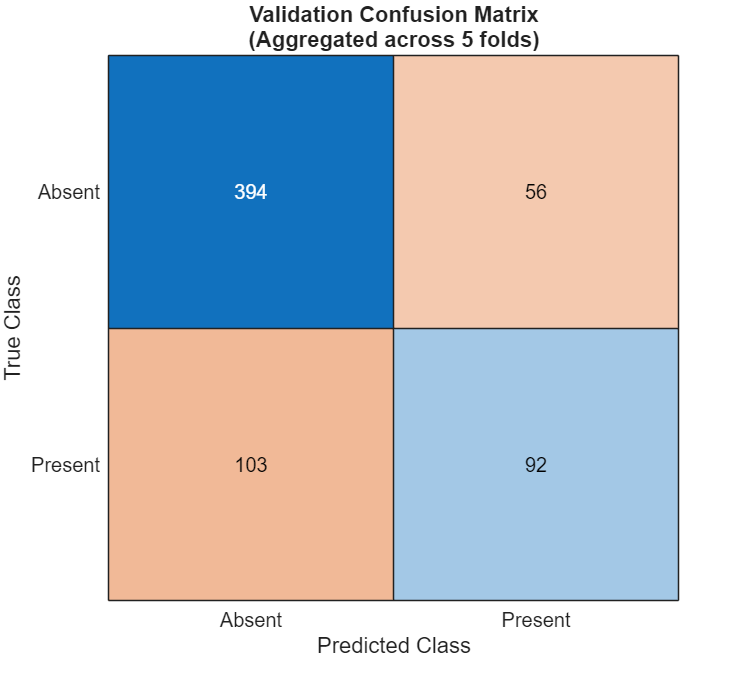


% Visualize - CORRECTED METHOD
figure('Name', 'Validation Confusion Matrix (Aggregated)', 'Position', [100 100 500 450]);

% Create vectors for confusionchart
% We need to create actual/predicted label vectors
total_samples = TN_total + FP_total + FN_total + TP_total;

actual_labels = categorical([...
    repmat({'Absent'}, TN_total, 1); ...
    repmat({'Absent'}, FP_total, 1); ...
    repmat({'Present'}, FN_total, 1); ...
    repmat({'Present'}, TP_total, 1)], ...
    {'Absent', 'Present'});

predicted_labels = categorical([...
    repmat({'Absent'}, TN_total, 1); ...
    repmat({'Present'}, FP_total, 1); ...
    repmat({'Absent'}, FN_total, 1); ...
    repmat({'Present'}, TP_total, 1)], ...
    {'Absent', 'Present'});

cm = confusionchart(actual_labels, predicted_labels);
cm.Title = sprintf('Validation Confusion Matrix\n(Aggregated across %d folds)', K_FOLDS);

%cm.RowSummary = 'row-normalized';
%cm.ColumnSummary = 'column-normalized';

fprintf('✓ Confusion matrix visualization created\n\n');

✓ Confusion matrix visualization created



%% BLOCK 11: ROC AND AUC CURVES
fprintf('========================================\n');

fprintf('ROC CURVES AND AUC\n');

ROC CURVES AND AUC


fprintf('========================================\n\n');


% Aggregate all training data
all_train_scores = vertcat(roc_data.train_scores{:});
all_train_labels = vertcat(roc_data.train_labels{:});

% Aggregate all validation data
all_val_scores = vertcat(roc_data.val_scores{:});
all_val_labels = vertcat(roc_data.val_labels{:});

% Calculate ROC curves
[Xroc_train, Yroc_train, ~, AUC_train] = perfcurve(all_train_labels, all_train_scores, 'Present');
[Xroc_val, Yroc_val, ~, AUC_val] = perfcurve(all_val_labels, all_val_scores, 'Present');

fprintf('AUC Results (Aggregated):\n');

AUC Results (Aggregated):


fprintf('  Training AUC:   %.4f\n', AUC_train);

  Training AUC:   0.9694


fprintf('  Validation AUC: %.4f\n\n', AUC_val);

  Validation AUC: 0.7179



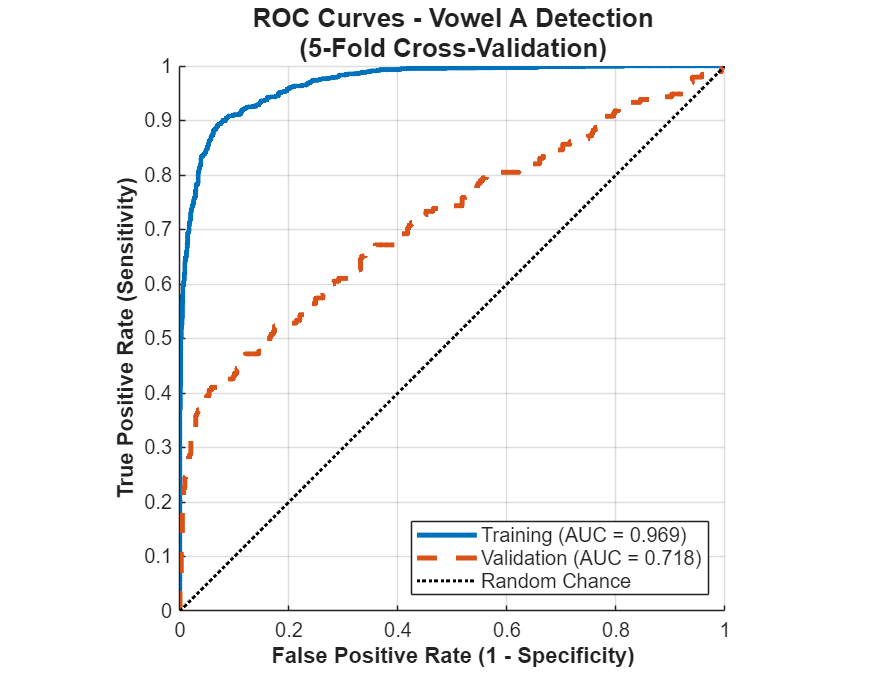


% Plot ROC Curves
figure('Name', 'ROC Curves - K-Fold Cross-Validation', 'Position', [150 150 700 550], 'Color', 'w');
hold on;

% Plot curves
plot(Xroc_train, Yroc_train, 'LineWidth', 2.5, 'Color', [0 0.4470 0.7410], ...
     'DisplayName', sprintf('Training (AUC = %.3f)', AUC_train));
plot(Xroc_val, Yroc_val, 'LineWidth', 2.5, 'Color', [0.8500 0.3250 0.0980], ...
     'LineStyle', '--', 'DisplayName', sprintf('Validation (AUC = %.3f)', AUC_val));

% Random chance line
plot([0 1], [0 1], 'k:', 'LineWidth', 1.5, 'DisplayName', 'Random Chance');

% Formatting
xlabel('False Positive Rate (1 - Specificity)', 'FontWeight', 'bold', 'FontSize', 11);
ylabel('True Positive Rate (Sensitivity)', 'FontWeight', 'bold', 'FontSize', 11);
title(sprintf('ROC Curves - Vowel A Detection\n(%d-Fold Cross-Validation)', K_FOLDS), ...
      'FontSize', 13, 'FontWeight', 'bold');
legend('Location', 'SouthEast', 'FontSize', 10);
grid on;
axis square;
xlim([0 1]);
ylim([0 1]);
hold off;


fprintf(' ROC curves plotted\n\n');

 ROC curves plotted



%% BLOCK 12: HELPER FUNCTION
% Place at the end of script

function features = extractLSTMFeatures(table, idx, freqMin, freqMax, sampleRate)
    % Extract spectrogram features
    spec1 = abs(single(table.EMG_ch1_Spectrogram{idx}));
    spec2 = abs(single(table.EMG_ch2_Spectrogram{idx}));
    
    % Filter frequency range
    freqsSpec = linspace(0, sampleRate/2, size(spec1,1));
    freqIdxSpec = (freqsSpec >= freqMin) & (freqsSpec <= freqMax);
    spec1_filtered = spec1(freqIdxSpec, :);
    spec2_filtered = spec2(freqIdxSpec, :);
    
    currentWidth = size(spec1_filtered, 2);
    
    % Resize to standard size
    spec1_resized = imresize(spec1_filtered, [450, currentWidth]);
    spec2_resized = imresize(spec2_filtered, [450, currentWidth]);
    
    % Stack features
    features = [spec1_resized; spec2_resized];
    features = single(features);
end